# Numerical integration

## Taks 1

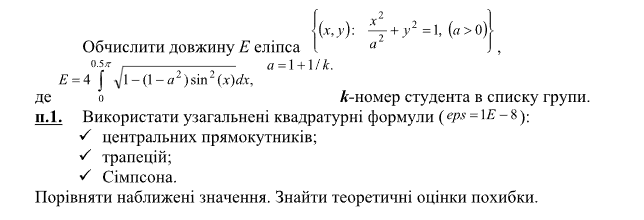

**Ідея (схематично):**

- центральних прямокутників: береться сума по лівому/центаральному/правому значенню функції на інтервалі

- трапецій - на відміну від центр.прям. береться середнє від суми значень по боках, а не просто $f(x_{0.5})$

- Сімпсона - ~трапеція, але з підвищенною точністю

a = 1 + 1/8

a = 1.1250

func = eval(['@(x)' 'sqrt(1 - (1 - a^2)*sin(x)^2)']);

n = 2000;
area1 = centerRectangleCalculator(func, 0, pi/2, n)

area1 = 1.6704

n = 1000;
area2 = trapezoidCalculator(func, 0, pi/2, n)

area2 = 1.6704

n = 1000;
area3 = simpsonCalculator(func, 0, pi/2, n)

area3 = 1.6704

## Taks 2

**Ідея (схематично):**

- береться сума по таких вагах, щоб формула була точна для полінома 2n-1 степіня. важливо: $p(x) ~ 1$

integralCR3 = gaussChristoffelCalculator(func, 0, pi/2, 3)

integralCR3 = 1.6704

integralCR4 = gaussChristoffelCalculator(func, 0, pi/2, 4)

integralCR4 = 1.6704

integralCR5 = gaussChristoffelCalculator(func, 0, pi/2, 5)

integralCR5 = 1.6704


% теоретичні оцінки ~ 0.0024 / 0.0003 / 10^-8

export("Computational methods/Lab1.mlx")

ans = 'E:\Work\Applied math\Matlab\Computational methods\Lab1.pdf'

function result = gaussChristoffelCalculator(func, a, b, n)
    result = 0;

    if n < 1 || n > 6
        error("gaussChristoffel: n < 1 or n > 6");
    end

    if a > b
        error("gaussChristoffel: a > b");
    end

    % set weights and nodes
    switch n
        case 1
            nodes = 0;
            weights = 2;
        case 2
            nodes = [-0.577350, 0.577350];
            weights = [1, 1];
        case 3
            nodes = [-0.774597, 0.000000, 0.774597];
            weights = [0.555556, 0.888889, 0.555556];
        case 4
            nodes = [-0.861136, -0.339981, 0.339981, 0.861136];
            weights = [0.347855, 0.652145, 0.652145, 0.347855];
        case 5
            nodes = [-0.906180, -0.538469, 0.000000, 0.538469, 0.906180];
            weights = [0.236927, 0.478629, 0.568889, 0.478629, 0.236927];
        case 6
            nodes = [-0.932470, -0.661209, -0.238619, 0.238619, 0.661209, 0.932470];
            weights = [0.171324, 0.360762, 0.467914, 0.467914, 0.360762, 0.171324];
    end

    % transform if [a, b] != [-1, 1]
    if a ~= -1 || b ~= 1
        ab = 0.5 .* (a + b); % .* - element-wise multiplication
        ba = 0.5 .* (b - a); 
        
        nodes = ab + ba .* nodes;
        weights = ba .* weights;
    end

    % compute, finally
    for i=1:n
        result = result + weights(i) * func(nodes(i));
    end
end

function result = centerRectangleCalculator(func, a, b, n)

    if a > b
        error("centerRectangle: a > b");
    end

    result = 0;
    step = (b - a) / n;

    xi = a;
    xj = a + step;

    for i=1:n
        xm = (xi + xj) / 2;
        result = result + func(xm) * step;
        xi = xj;
        xj = xj + step;
    end
end

function result = trapezoidCalculator(func, a, b, n)

    if a > b
        error("centerRectangle: a > b");
    end
    
    result = 0;
    step = (b - a) / n;

    xi = a;
    xj = a + step;

    for i=1:n
        result = result + (func(xj) + func(xi))/2 * step;
        xi = xj;
        xj = xj + step;
    end
end

function result = simpsonCalculator(func, a, b, n)

    if a > b
        error("centerRectangle: a > b");
    end
    
    result = 0;
    step = (b - a) / n;

    xi = a;
    xj = a + step;

    for i=1:n
        xm = (xi + xj) / 2;

        result = result + (func(xj) + 4*func(xm) + func(xi))/6 * step;
        xi = xj;
        xj = xj + step;
    end
end